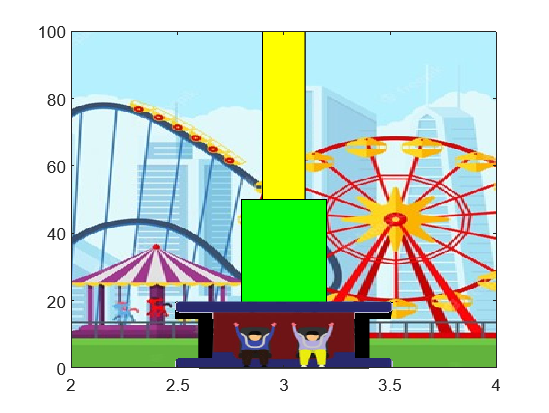

v0 = 0;
y0 = 100;
t_f = 30;
t_i = 0;
n = 200;
m = input("Escribe el valor de la masa: ");
h = (t_f - t_i)/n;
g = 9.81;
[kh_img, ~, kh_alpha] = imread("ppl.png");
backgr = imread("parque.jpg");

%kh_img = imresize(kh_img, 0.025)
%if size(kh_img,3) == 1
%    kh_img = repmat(kh_img,[1 1 3]); 
%end

kh_img = flipud(kh_img);
backgr = flipud(backgr);


t=t_i:h:t_f;

f = @(y,v,t) -9.81;
f1 = @(y,v,t,k,m) (k*v/m) - g;

y = zeros(1, n+1);
v = zeros(1, n+1);
a = zeros(1, n+1);

y(101) = y0;
v(101) = v0;
a(101) = -9.8;

limDer = 2.4;

for i=1:n
y(i) = i;
end

for i=101:n

    if y(i) > 50
        k1 = h*v(i);
        l1 = h*f(y(i), v(i), t(i));
    
        k2 = h*(v(i)+l1/2);
        l2 = h*f(y(i)+k1/2, v(i)+l1/2, t(i)+h/2);
    
        k3 = h*(v(i)+l2/2);
        l3 = h*f(y(i)+k2/2, v(i)+l2/2, t(i)+h/2);
    
        k4 = h*(v(i)+l3);
        l4 = h*f(y(i)+k3, v(i)+l3, t(i)+h);
    
        y(i+1) = y(i) + (1/6)*(k1+2*k2+2*k3+k4);
        v(i+1) = v(i) + (1/6)*(l1+2*l2+2*l3+l4);
        a(i+1) = f(y(i), v(i), t(i));
    end

    if y(i) <= 50 && y(i) > 15
        k = -2.13*m;
        k1=h*v(i);
        l1=h*f1(y(i), v(i), t(i), k, m);

        k2=h*(v(i)+l1/2);
        l2=h*f1(y(i)+k1/2, v(i)+l1/2, t(i)+h/2, k, m);

        k3=h*(v(i)+l2/2);
        l3=h*f1(y(i)+k2/2, v(i)+l2/2, t(i)+h/2, k, m);

        k4=h*(v(i)+l3);
        l4=h*f1(y(i)+k3, v(i)+l3, t(i)+h, k, m);
    
        y(i+1)=y(i)+(k1+2*k2+2*k3+k4)/6;
        v(i+1)= v(i)+(l1+2*l2+2*l3+l4)/6;
        a(i+1) = f1(y(i), v(i), t(i), k, m);
        
    end

    if y(i) <= 15
        k = -4.933*m;
        k1=h*v(i);
        l1=h*f1(y(i), v(i), t(i), k, m);

        k2=h*(v(i)+l1/2);
        l2=h*f1(y(i)+k1/2, v(i)+l1/2, t(i)+h/2, k, m);

        k3=h*(v(i)+l2/2);
        l3=h*f1(y(i)+k2/2, v(i)+l2/2, t(i)+h/2, k, m);

        k4=h*(v(i)+l3);
        l4=h*f1(y(i)+k3, v(i)+l3, t(i)+h, k, m);
    
        y(i+1)=y(i)+(k1+2*k2+2*k3+k4)/6;
        v(i+1)= v(i)+(l1+2*l2+2*l3+l4)/6;
        a(i+1) = f1(y(i), v(i), t(i), k, m);
    end
    if y(i) <= 0
        break
    end
end
v(201) = 0;
y(201) = 0;


for n=1:length(t)-1
    clf;
    b_img = image(backgr, 'xdata', [0 4],'ydata',[0 100]);
    rectangle('position',[2.9,0,0.2,100],'FaceColor', 'y');
    rectangle('position',[2.8,0,0.4,50],'FaceColor', 'g');
    rectangle('position',[2.6,0,0.8,15],'FaceColor', 'black');
    hold on
    %r = rectangle('position',[limDer, y(n),1.2,5],'FaceColor','r','Curvature',0.5,'EdgeColor','r');
    img = image(kh_img,'xdata',[2.4 3.6],'ydata',[y(n) y(n)+20], 'AlphaData', im2double(kh_alpha));
 
    
    ylim([-3,100])
    xlim([2,4])
    axis([2 4 0 100])
    axis xy;
            
    drawnow
    hold off
end

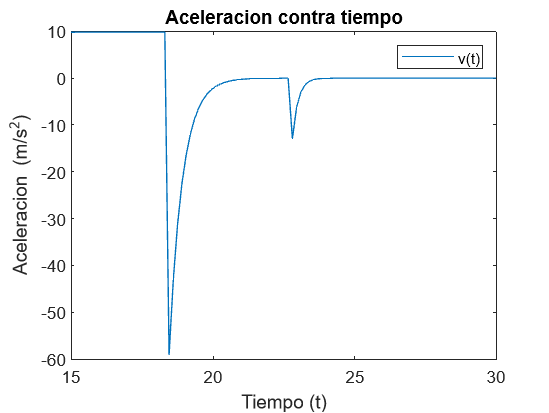


vp = -1.*v;
ap = -1.*a;

plot(t(101:end),ap(101:end))
title("Aceleracion contra tiempo")
xlabel("Tiempo (s)")
ylabel("Aceleracion (m/s^2)")
legend("a(t)")

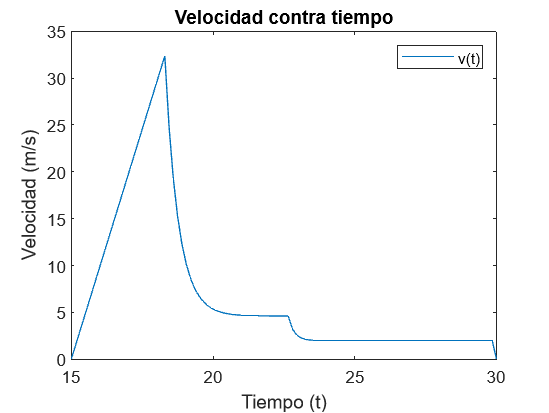


plot(t(101:end),vp(101:end))
title("Velocidad contra tiempo")
xlabel("Tiempo (s)")
ylabel("Velocidad (m/s)")
legend("v(t)")

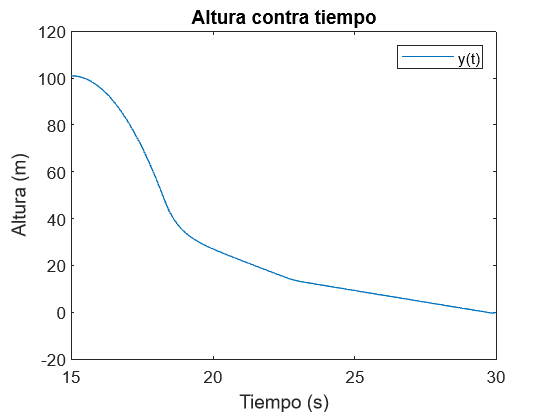


plot(t(101:end),y(101:end))
title("Altura contra tiempo")
xlabel("Tiempo (s)")
ylabel("Altura (m)")
legend("y(t)")